# Generarea unor cuadraturi de tip Gauss

P1. Implementati functii ce genereaza formule de cuadratura gaussiene pentru ponderile clasice date in tabela 1.

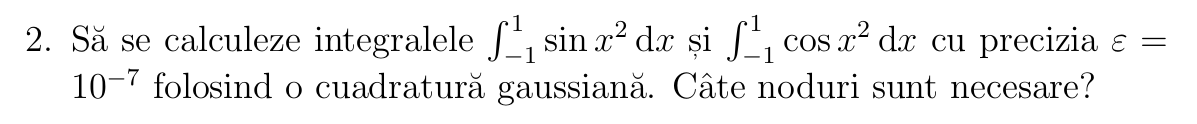

f1 = @(x) sin(x.^2);
f2 = @(x) cos(x.^2);
epsilon = 1e-7;
n = 2;
I1 = 0; I2 = 0; err1 = 1; err2 = 1;
while err1 > epsilon | err2 > epsilon
    [x, w] = gauss_legendre(n);
    x = x(:); w = w(:); % ensure column vectors
    I1_new = sum(w .* f1(x));
    I2_new = sum(w .* f2(x));
    err1 = abs(I1_new - I1);
    err2 = abs(I2_new - I2);
    I1 = I1_new;
    I2 = I2_new;
    n = n + 1;
end
disp(['valoare integrala sin(x^2): ', num2str(I1), ', noduri: ', num2str(n-1)]);

valoare integrala sin(x^2): 0.62054, noduri: 8


disp(['valoare integrala cos(x^2): ', num2str(I2), ', noduri: ', num2str(n-1)]);

valoare integrala cos(x^2): 1.809, noduri: 8


P3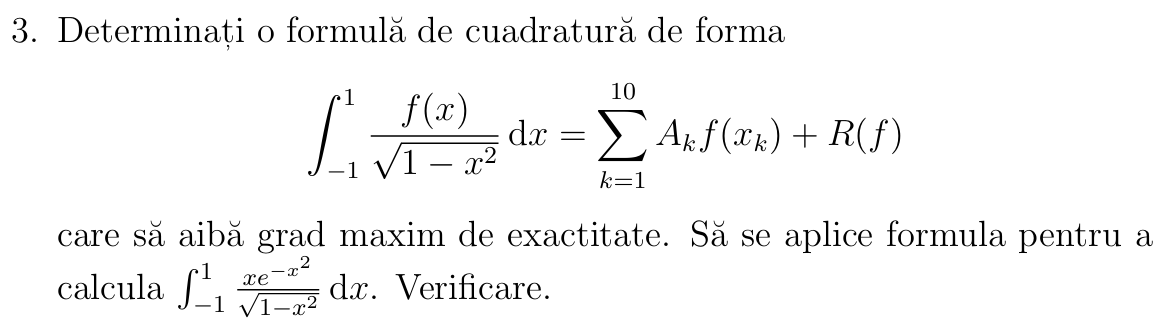

% problema 3: cuadratura gauss-chebyshev tip 1 pentru sqrt(1-x^2) in numitor

n = 10;
[x, w] = gauss_chebyshev1(n);
f = @(x) x .* exp(-x.^2);
I = sum(w .* f(x));
disp(['valoare integrala: ', num2str(I)]);

valoare integrala: 8.3267e-17


P4.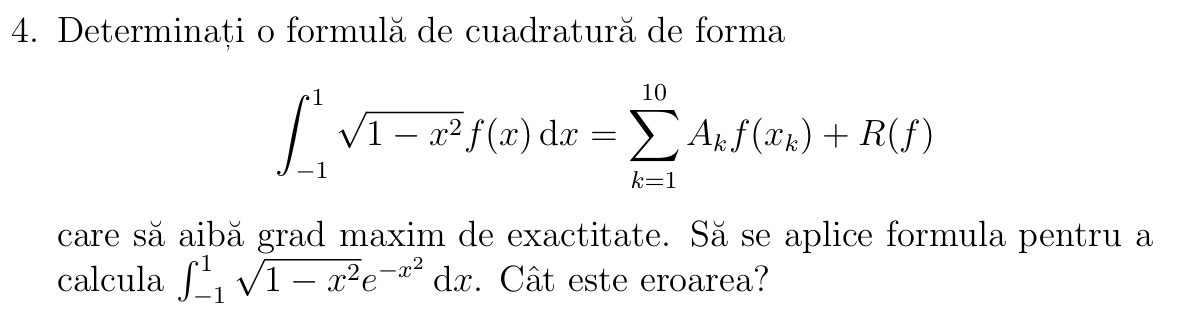

% problema 4: cuadratura gauss-chebyshev tip 2 pentru sqrt(1-x^2) in pondere

n = 10;
[x, w] = gauss_chebyshev2(n);
f = @(x) exp(-x.^2);
I = sum(w .* f(x));
% calcul exact cu quadgk pentru verificare
I_exact = integral(@(x) exp(-x.^2) .* sqrt(1-x.^2), -1, 1);
eroare = abs(I - I_exact);
disp(['valoare integrala: ', num2str(I), ', eroare: ', num2str(eroare)]);

valoare integrala: 1.2589, eroare: 2.6312e-13


P5.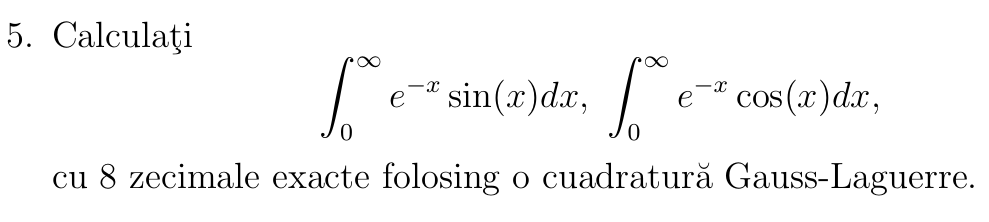

% problema 5: cuadratura gauss-laguerre pentru integrale pe [0,inf)

n = 20;
[x, w] = gauss_laguerre(n);
I1 = sum(w .* sin(x));
I2 = sum(w .* cos(x));
disp(['integrala e^{-x}sin(x): ', num2str(I1)]);

integrala e^{-x}sin(x): 0.58633     0.14658    0.018323   0.0015269  9.5431e-05  4.7716e-06  1.9882e-07  7.1005e-09  2.2189e-10  6.1637e-12  1.5409e-13  3.5021e-15   7.295e-17  1.3992e-18  2.4237e-20  3.3374e-22  2.6691e-24  8.4117e-27  6.6545e-30  4.9542e-34


disp(['integrala e^{-x}cos(x): ', num2str(I2)]);

integrala e^{-x}cos(x): 0.85931     0.21483    0.026853   0.0022378  0.00013986  6.9931e-06  2.9138e-07  1.0406e-08   3.252e-10  9.0333e-12  2.2583e-13  5.1325e-15  1.0691e-16  2.0506e-18  3.5521e-20  4.8912e-22  3.9118e-24  1.2328e-26  9.7527e-30  7.2608e-34


P6.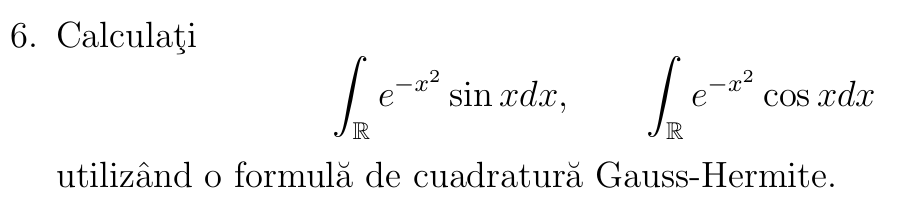

% problema 6: cuadratura gauss-hermite pentru integrale pe (-inf,inf)

n = 20;
[x, w] = gauss_hermite(n);
I1 = sum(w .* sin(x));
I2 = sum(w .* cos(x));
disp(['integrala e^{-x^2}sin(x): ', num2str(I1)]);

integrala e^{-x^2}sin(x): 5.5536e-28  9.8228e-25  2.7793e-22  1.9482e-20   5.421e-19  9.1073e-18  5.8981e-17  2.3592e-16  6.9389e-16  1.0547e-15  8.3267e-16  4.7184e-16  3.0531e-16  2.7756e-17  9.1073e-18    5.15e-19    1.44e-20  1.9852e-22  1.1374e-24  5.5536e-28


disp(['integrala e^{-x^2}cos(x): ', num2str(I2)]);

integrala e^{-x^2}cos(x): -3.8058e-13 -7.5101e-10  -1.854e-07  -1.332e-05 -0.00038979  -0.0055374   -0.042354     -0.1861    -0.48938    -0.78909    -0.78909    -0.48938     -0.1861   -0.042354  -0.0055374 -0.00038979  -1.332e-05  -1.854e-07 -7.5101e-10 -3.8058e-13


P7. 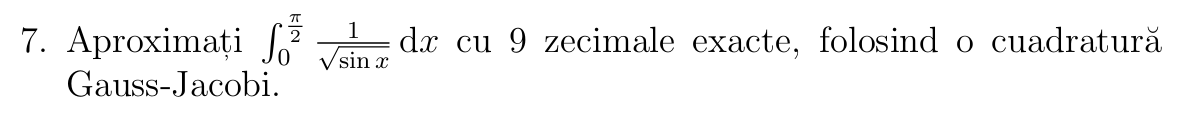

% problema 7: cuadratura gauss-jacobi pentru integrala 0->pi/2 sqrt(sin(x))dx

n = 20;
alfa = -0.5; beta = 0;
[x, w] = gauss_jacobi(n, alfa, beta);
% schimbare de variabila: x = cos(t), t in [0, pi/2]
f = @(x) sqrt(sin(acos(x)));
I = sum(w .* f(x));
disp(['integrala sqrt(sin(x)) pe [0,pi/2]: ', num2str(I)]);

integrala sqrt(sin(x)) pe [0,pi/2]: 2.34584+0.99922i         0.665373+0.283418i          1.02131+0.435031i          1.25716+0.535493i          1.45027+0.617746i          1.61783+0.689121i          1.76429+0.751507i          1.89052+0.805274i          1.99608+0.850239i           2.0799+0.885942i          2.14042+0.911721i          2.17551+0.926668i          2.18213+0.929487i          2.15561+0.918191i          2.08805+0.889411i          1.96456+0.836811i          1.75394+0.747096i          1.38578+0.590277i         0.746401+0.317932i           9.53078+4.05967i
